## G' matrix and other variables with default parameter values

## (Figure 4I, S5B, D, E)

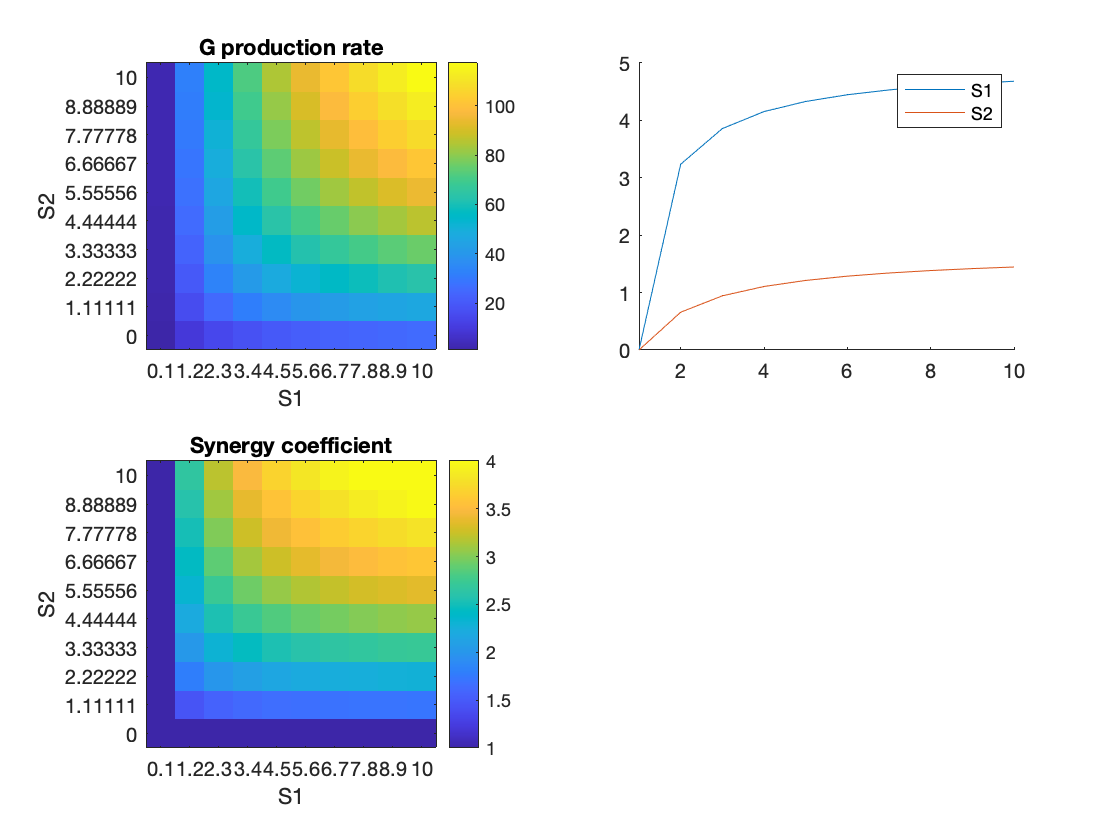


params = reset_params();

n = 10;
G_matrix = zeros(n, n);
A_matrix = zeros(n, n);
r_matrix = zeros(n, n);
synergy_matrix = zeros(n, n); 

params.K_S1A = 10; 
S1_vals = linspace(0.1, 10, n); 
S2_vals = linspace(0, 10, n);

i = 1;
for S1 = S1_vals
    j = 1;
    for S2 = S2_vals
        [G, A, r] = G_calc(params, S1, S2);
        G_matrix(j, i) = G;
        A_matrix(j, i) = A;
        r_matrix(j, i) = r;
        synergy_matrix(j, i) = G_matrix(j, i)/(G_matrix(j, 1) + G_matrix(1, i));
        j = j + 1;
    end
    i = i + 1;
end

f1 = figure;
subplot(2, 2, 1);
imagesc(G_matrix(end:-1:1, :)/G_matrix(1, 1));
xticks(1:length(S1_vals)); yticks(1:length(S1_vals));
xticklabels(S1_vals); yticklabels(S2_vals(end:-1:1));
xlabel('S1'); ylabel('S2');
title('G production rate');
colorbar();

subplot(2, 2, 2); hold on;
plot(1:n, log2(G_matrix(1, :)/G_matrix(1, 1))); 
plot(1:n, log2(G_matrix(:, 1)/G_matrix(1, 1))); legend({'S1', 'S2'})
xlim([1 10])

subplot(2, 2, 3);
imagesc(synergy_matrix(end:-1:1, :), [1 4]);
xticks(1:length(S1_vals)); yticks(1:length(S1_vals));
xticklabels(S1_vals); yticklabels(S2_vals(end:-1:1));
xlabel('S1'); ylabel('S2');
title('Synergy coefficient');
colorbar();

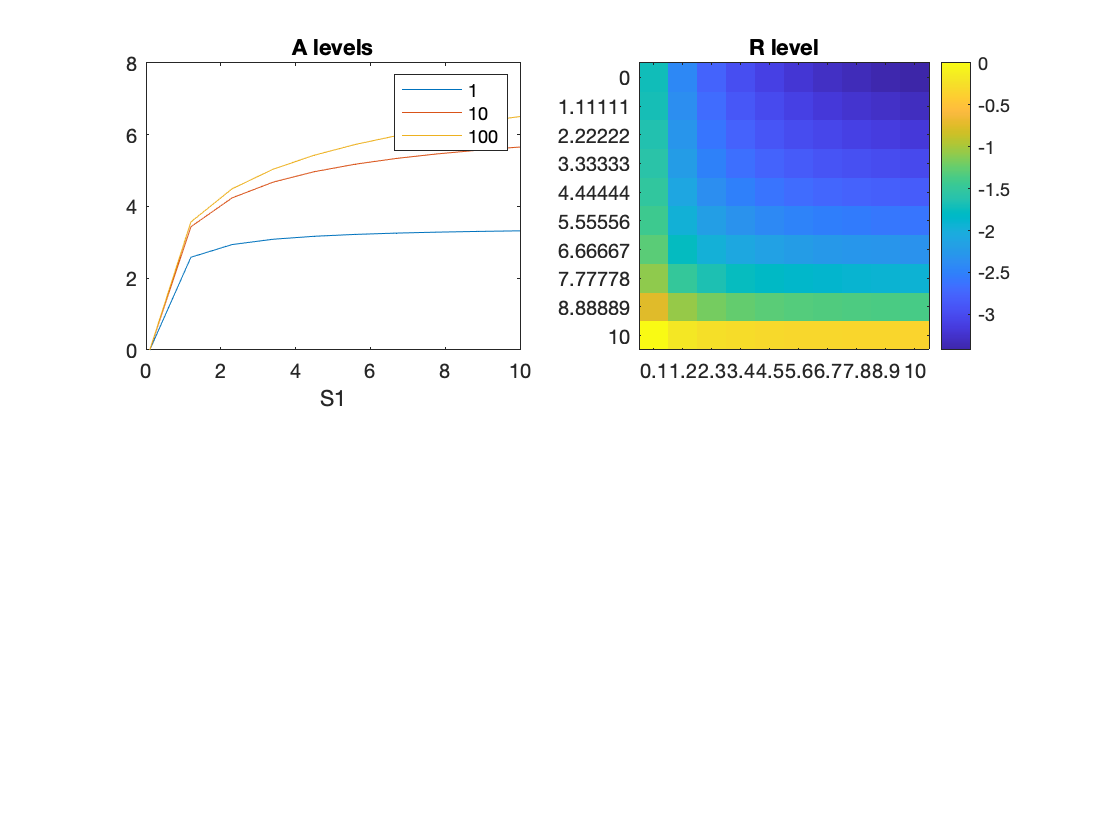

f2 = figure;
subplot(2, 2, 2); imagesc(log2(r_matrix(end:-1:1, :)/r_matrix(1, 1))); 
xticklabels(S1_vals); yticklabels(S2_vals);
xticks(1:length(S1_vals)); yticks(1:length(S1_vals));
colorbar(); title('R level')

params = reset_params();
K_S1A_vals = [1, 10, 100];
A_vals = zeros(length(K_S1A_vals), length(S1_vals));
p = 1;
for K_S1A = K_S1A_vals
    
    params.K_S1A = K_S1A;
    s = 1;
    for S1 = S1_vals
        [~, A, ~] = G_calc(params, S1, 0);
        A_vals(p, s) = A;
        s = s + 1;
    end
    p = p + 1;
end

subplot(2, 2, 1); plot(S1_vals, log2(bsxfun(@rdivide, A_vals, A_vals(:, 1)))); title('A levels');
xlabel('S1'); 
legend(string(K_S1A_vals))

## G' - dependence on S1 and r0

## Figure S5C

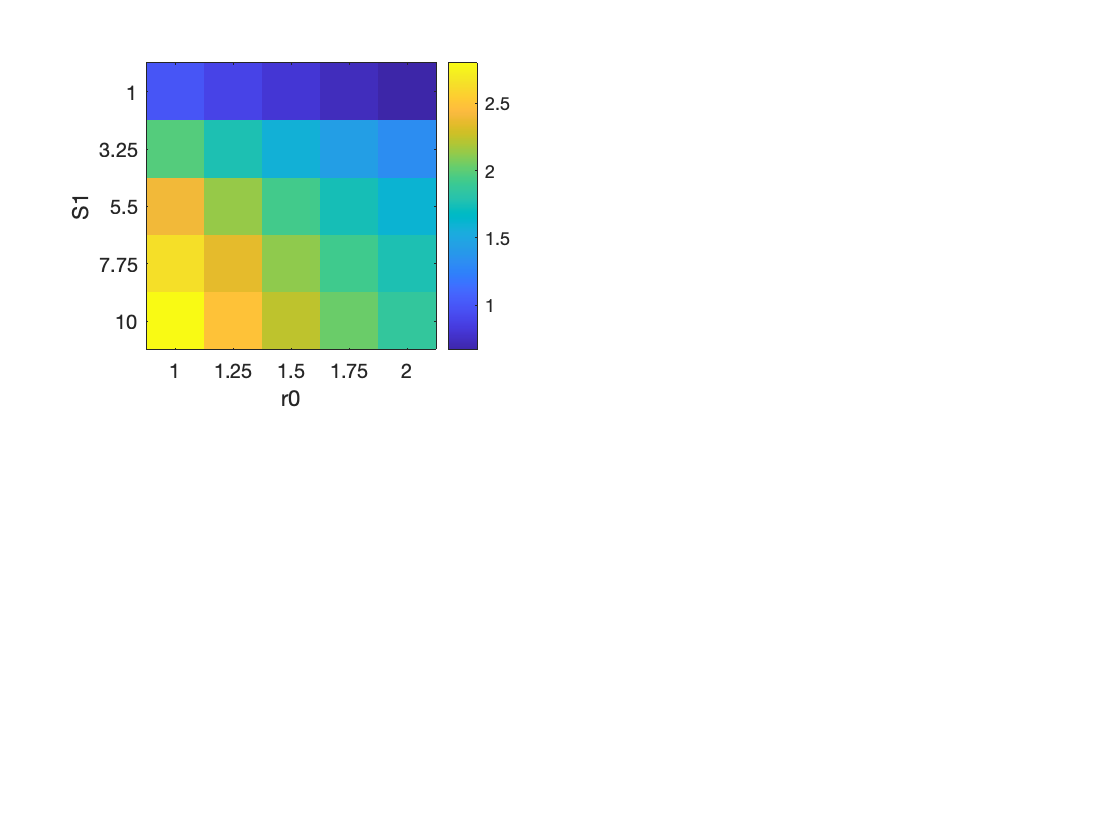

params = reset_params();

b_max = params.b_max;

K_R = 1;

% Note r0 = R0/K_R;
r0 = params.r0;

K_S1A = params.K_S1A;

n = 5;
G_matrix_AvR = zeros(n, n);
i = 1;

S1_vals = linspace(1, 10, n);
r0_vals = 0.1*linspace(r0, 2*r0, n);
for S1 = S1_vals
    j = 1;
    for r = r0_vals
        G = b_max*K_R*(1/(1 + r))*(S1/(S1 + K_S1A*(1 - b_max)));
        G_matrix_AvR(i, j) = G;
        j = j + 1;
    end
    i = i + 1;
end
f2 = figure;
subplot(2, 2, 1); 
imagesc(G_matrix_AvR/G_matrix_AvR(1, 1));
colorbar();
yticklabels(S1_vals);
ylabel('S1');
xticklabels(r0_vals);
xlabel('r0');

## Synergy - parameter scan

## Figure 4K, L

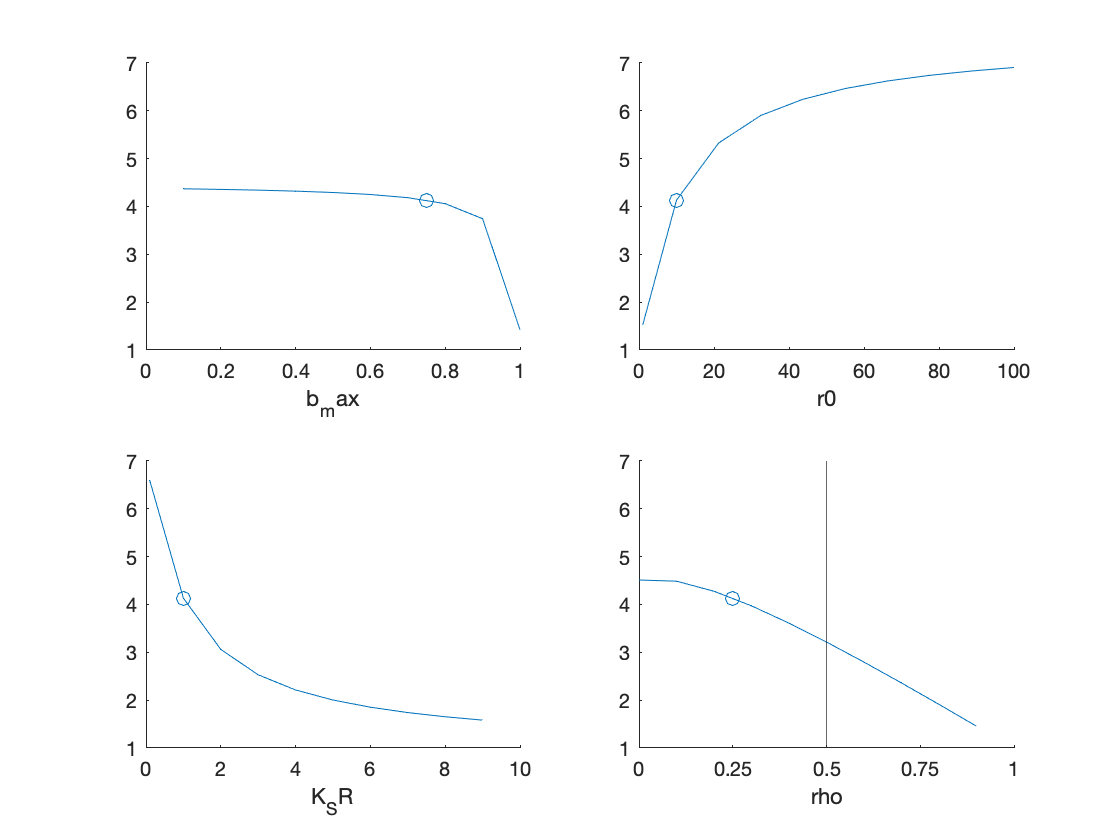

S1_vals = [0.1, 10];
S2_vals = [0, 10];

f3 = figure;

params = reset_params();
synergy_coeff = zeros(1, 10);
% b_max = 1/(1 + K_AG)
i = 1;
b_max_range = 0.1:0.1:1;
for b_max_i = b_max_range
    params.b_max = b_max_i;    
    synergy_coeff(i) = syn_coeff_calc(params, S1_vals, S2_vals);
    i = i + 1;
end

subplot(2, 2, 1); hold on;
h  = plot(b_max_range, synergy_coeff);
params = reset_params();
scatter(params.b_max, syn_coeff_calc(params, S1_vals, S2_vals), 50, h.Color)
ylim([1 7]);
xlabel('b_max');

synergy_coeff = zeros(1, 10);
% r0_scan
i = 1;
r0_range = [1, 10*linspace(1, 10, 9)];
for r0_i = r0_range
    params.r0 = r0_i;
    synergy_coeff(i) = syn_coeff_calc(params, S1_vals, S2_vals);
    i = i + 1;
end
subplot(2, 2, 2); hold on;
h = plot(r0_range, synergy_coeff);
params = reset_params();
scatter(params.r0, syn_coeff_calc(params, S1_vals, S2_vals), 50, h.Color)
ylim([1 7]);
xlabel('r0');

synergy_coeff = zeros(1, 10);
% K_SR_scan
i = 1;
K_SR_range = [0.1, linspace(1, 9, 9)];
for K_SR_i = K_SR_range
    params.K_SR = K_SR_i;
    synergy_coeff(i) = syn_coeff_calc(params, S1_vals, S2_vals);
    i = i + 1;
end
subplot(2, 2, 3); hold on;
h = plot(K_SR_range, synergy_coeff);
params = reset_params();
scatter(params.K_SR, syn_coeff_calc(params, S1_vals, S2_vals), 50, h.Color)
ylim([1 7]);
xlabel('K_SR');


synergy_coeff = zeros(1, 10);
% im_factor scan
i = 1;
im_factor_range = 0:0.1:0.9;
for im_factor_i = im_factor_range
    params.im_factor = im_factor_i;
    synergy_coeff(i) = syn_coeff_calc(params, S1_vals, S2_vals);
    i = i + 1;
end
ax = subplot(2, 2, 4); hold on;
h = plot(im_factor_range, synergy_coeff);
params = reset_params();
scatter(params.im_factor, syn_coeff_calc(params, S1_vals, S2_vals), 50, h.Color);
ylim([1 7]);
xticks([0 0.25 0.5 0.75 1])
%ax.YAxisLocation = 'origin';
xline(0.5)
xlabel('rho');

function [G, A, r] = G_calc(params, S1, S2)

    % b_max has to be [0, 1] -> sets the sensitivity to A
    b_max = params.b_max;
    
    base_rate = params.base_rate;
    
    % K_R acts as a scaling factor
    K_R = 1;
    
    % Note r0 = R0/K_R;
    r0 = params.r0;
    
    K_S1A = params.K_S1A;
    K_SR = params.K_SR;
    
    im_factor = params.im_factor;
    
    % note the rep_factor_total has to be <= 1
    rep_factor_total = params.rep_factor_total;
    
    A = S1/(S1 + K_S1A);
    r = r_calc(r0, S1, S2, K_SR, im_factor, rep_factor_total);
    G = b_max*(base_rate + (S1/(S1 + K_S1A*(1 - b_max))))*K_R*(1/(1 + r));

end


function r = r_calc(r0, S1, S2, K_SR, im_factor, rep_factor_total)
    s1_mask = 1;
    r = r0*(1 - s1_mask*im_factor*S1/(S1 + K_SR) - (rep_factor_total - im_factor)*S2/(S2 + K_SR));
end


function [synergy_coeff, G_max] = syn_coeff_calc(params, S1_vals, S2_vals)
    G_matrix = zeros(length(S1_vals), length(S2_vals));
    sn1 = 1;
    for S1 = S1_vals
        sn2 = 1;
        for S2 = S2_vals
            [G, ~, ~] = G_calc(params, S1, S2);
            G_matrix(sn1, sn2) = G;
            sn2 = sn2 + 1;
        end
        sn1 = sn1 + 1;
    end
    synergy_coeff = G_matrix(2, 2)/(G_matrix(1, 2) + G_matrix(2, 1));
    G_max = G_matrix(2, 2);
end

function params = reset_params()

    params = struct;
    params.K_S1A = 10;
    params.base_rate = 0;
    
    params.b_max = 0.75;
    params.r0 = 10;
    params.K_SR = 1;
    params.im_factor = 0.25;
    params.rep_factor_total = 1;
end
